% Presetting
syms x y z omega phi psi;
PosExtract=[0; 0; 0; 1];
p(x, y, z)=[x; y; z];
Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];
Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];
Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

% Body Kinematics
syms L W omega phi psi xm ym zm;

% Global to Body
anglemx=omega;
anglemy=phi;
anglemz=psi;
pm=[xm ym zm].';
Rotm=Rotx(anglemx)*Roty(anglemy)*Rotz(anglemz);
Tm=HomogeneousTransform(Rotm, pm, 1);

% Body to Right Front Shoulder
anglemRF=pi/2;
pmRF=[L/2 0 W/2].';
RotmRF=Roty(anglemRF);
TmRF=HomogeneousTransform(RotmRF, pmRF, 1);

% Body to Right Back Shoulder
anglemRB=pi/2;
pmRB=[-L/2 0 W/2].';
RotmRB=Roty(anglemRB);
TmRF=HomogeneousTransform(RotmRB, pmRB, 1);

% Body to Left Front Shoulder
anglemLF=-pi/2;
pmLF=[L/2 0 -W/2].';
RotmLF=Roty(anglemLF);
TmRF=HomogeneousTransform(RotmLF, pmLF, 1);

% Body to Left Back Shoulder
anglemLB=-pi/2;
pmLB=[-L/2 0 -W/2].';
RotmLB=Roty(anglemLB);
TmRF=HomogeneousTransform(RotmLB, pmLB, 1);

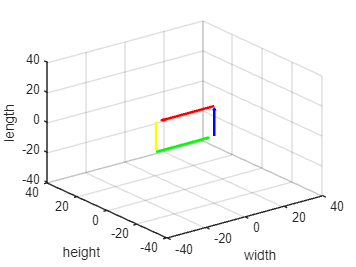

% Body Kinematics test by plot graph

% Global to Body
anglemx=0;
anglemy=0;
anglemz=0;
pm=[0 0 0].';
Rotm=Rotx(anglemx)*Roty(anglemy)*Rotz(anglemz);
Tm=HomogeneousTransform(Rotm, pm, 1);

% Body to Right Front Shoulder
anglemRF=pi/2;
pmRF=[30/2 0 20/2].';
RotmRF=Roty(anglemRF);
TmRF=HomogeneousTransform(RotmRF, pmRF, 1);

% Body to Right Back Shoulder
anglemRB=pi/2;
pmRB=[-30/2 0 20/2].';
RotmRB=Roty(anglemRB);
TmRB=HomogeneousTransform(RotmRB, pmRB, 1);

% Body to Left Front Shoulder
anglemLF=-pi/2;
pmLF=[30/2 0 -20/2].';
RotmLF=Roty(anglemLF);
TmLF=HomogeneousTransform(RotmLF, pmLF, 1);

% Body to Left Back Shoulder
anglemLB=-pi/2;
pmLB=[-30/2 0 -20/2].';
RotmLB=Roty(anglemLB);
TmLB=HomogeneousTransform(RotmLB, pmLB, 1);

TRF=Tm*TmRF;
TRB=Tm*TmRB;
TLF=Tm*TmLF;
TLB=Tm*TmLB;

pRF=TRF*PosExtract;
pRB=TRB*PosExtract;
pLF=TLF*PosExtract;
pLB=TLB*PosExtract;

front=pRF-pLF;
right=pRB-pRF;
back=pLB-pRB;
left=pLF-pLB;

figure
quiver3(pLF(1,1), pLF(2,1), pLF(3,1), front(1,1), front(2,1), front(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pRF(1,1), pRF(2,1), pRF(3,1), right(1,1), right(2,1), right(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pRB(1,1), pRB(2,1), pRB(3,1), back(1,1), back(2,1), back(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pLB(1,1), pLB(2,1), pLB(3,1), left(1,1), left(2,1), left(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Right Front Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1;
p01=p(0,0,L1);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Right Front UpperArm to LowArm
angle23=theta2;
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Right Front LowArm to Foot
angle34=theta3;
p34=p(L3*cos(theta3),L3*sin(theta3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Right Front Shoulder to UpperArm
T02=T01*T12;
T02=simplify(T02);
% Right Front Shoulder to LowArm
T03=T02*T23;
T03=simplify(T03);
% Right Front Shoulder to Foot
T04=T03*T34;
T04=simplify(T04);

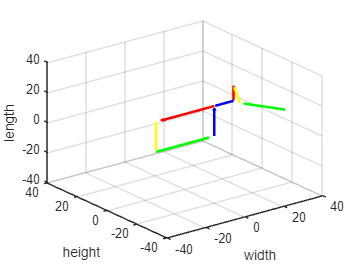

% Right Front Leg Kinematics test by plot graph

% Right Front Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Right Front UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Right Front LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Right Front Shoulder to UpperArm
T02=T01*T12;
% Right Front Shoulder to LowArm
T03=T02*T23;
% Right Front Shoulder to Foot
T04=T03*T34;

pRFU=TRF*T01*PosExtract;
pRFL1=TRF*T02*[0 0 10 1].';
pRFL2=TRF*T03*PosExtract;
pRFF=TRF*T04*PosExtract;

RFS=pRF-pRFU;
RFU=pRFU-pRFL1;
RFL1=pRFL1-pRFL2;
RFL2=pRFL2-pRFF;

quiver3(pRFU(1,1), pRFU(2,1), pRFU(3,1), RFS(1,1), RFS(2,1), RFS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pRFL1(1,1), pRFL1(2,1), pRFL1(3,1), RFU(1,1), RFU(2,1), RFU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pRFL2(1,1), pRFL2(2,1), pRFL2(3,1), RFL1(1,1), RFL1(2,1), RFL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pRFF(1,1), pRFF(2,1), pRFF(3,1), RFL2(1,1), RFL2(2,1), RFL2(3,1), 'Color', 'green','LineWidth', 2)
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Right Back Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3;

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1;
p01=p(0,0,-L1);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=theta2;
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=theta3;
p34=p(L3*cos(theta3),L3*sin(theta3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
T02=simplify(T02)
% Right Front Shoulder to LowArm
T03=T02*T23
T03=simplify(T03)
% Right Front Shoulder to Foot
T04=T03*T34
T04=simplify(T04)

% Right Front Leg Kinematics test by plot graph

% Right Front Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,-10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
% Right Front Shoulder to LowArm
T03=T02*T23
% Right Front Shoulder to Foot
T04=T03*T34

p0=PosExtract;
p1=T01*PosExtract;
p2=T02*[0 0 10 1].';
p3=T03*PosExtract;
p4=T04*PosExtract;

Link1=p1-p0;
Link2=p2-p1;
Link3=p3-p2;
Link4=p4-p3;

figure
quiver3(p0(1,1), p0(2,1), p0(3,1), Link1(1,1), Link1(2,1), Link1(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(p1(1,1), p1(2,1), p1(3,1), Link2(1,1), Link2(2,1), Link2(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(p2(1,1), p2(2,1), p2(3,1), Link3(1,1), Link3(2,1), Link3(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(p3(1,1), p3(2,1), p3(3,1), Link4(1,1), Link4(2,1), Link4(3,1), 'Color', 'green','LineWidth', 2)
xlabel('width')
ylabel('height')
zlabel('length')
axis([-40 40 -40 40 -40 40])

% Left Front Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1
p01=p(0,0,L1)
Rot01=Rotz(angle01)
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2
angle12x=pi/2
p12=p(0, 0, 0)
Rot12=Rotz(angle12z)*Rotx(angle12x)
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=theta2
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z)
Rot23=Rotz(angle23)
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=theta3
p34=p(L3*cos(theta3),L3*sin(theta3),0)
Rot34=Rotz(angle34)
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
T02=simplify(T02)
% Right Front Shoulder to LowArm
T03=T02*T23
T03=simplify(T03)
% Right Front Shoulder to Foot
T04=T03*T34
T04=simplify(T04)

% Left Back Leg Kinematics
syms L1 L2xy L2z L3 theta1 theta2 theta3

% Right Front Shoulder to Preprocessing UpperArm
angle01=theta1
p01=p(0,0,L1)
Rot01=Rotz(angle01)
T01=HomogeneousTransform(Rot01, p01, 1)

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2
angle12x=pi/2
p12=p(0, 0, 0)
Rot12=Rotz(angle12z)*Rotx(angle12x)
T12=HomogeneousTransform(Rot12, p12, 1)

% Right Front UpperArm to LowArm
angle23=theta2
p23=p(L2xy*cos(theta2),L2xy*sin(theta2),L2z)
Rot23=Rotz(angle23)
T23=HomogeneousTransform(Rot23, p23, 1)

% Right Front LowArm to Foot
angle34=theta3
p34=p(L3*cos(theta3),L3*sin(theta3),0)
Rot34=Rotz(angle34)
T34=HomogeneousTransform(Rot34, p34, 1)

% Right Front Shoulder to UpperArm
T02=T01*T12
T02=simplify(T02)
% Right Front Shoulder to LowArm
T03=T02*T23
T03=simplify(T03)
% Right Front Shoulder to Foot
T04=T03*T34
T04=simplify(T04)